# **Project#1: EngineFaultDB - Feature Extraction**

**Class: Industrial AI & Automation**

**Author: GYEONHEAL AN(21900416), GARMA JIN(21900727)**

**Date: 2024-10-22**

### **Background Introduction**

**- Necessity**

- CO, HC, and CO2, contributing to environmental problems.

- High repair costs, unexpected downtime, potential financial and safety risks.

- Solving complicating problem sensor issues, pressure problems, injector defects

**- Technical Challenges**

- Traditional Method: Manual Inspections (e.g., fuel pressure measurements, OBD-2 scanners). 

- Labor-Intensive, Expensive, and Require Expert Knowledge.

**- Solution**

- By Applying Machine Learning, Classification to Identify Types of Engine Faults.

- Classification will Help Quickly Diagnose, Resolve Engine Faults, Enabling Fast, and Efficient Repairs.

### Problem Statement

**- Objective**

- By Developing a Model that Outperforms those Implemented in Existing Journals, Accurately Identifytypes of Engine faults, Providing Greater Speedand Precision in Engine Repairs.

**- Detailed Objectives**

- Classify Datasets by Machine Learning Model Using “EngineFaultDB” Datasets.

- Understand and Analysis Datasetsthrough FeatureAnalysis.

- Improve Model Performance through FeatureExtractionand FeatureReduction/Selection

- Compare the Model Performance with Baseline Journal.

### Baseline Survey & Datasets

- **Datasets: **https://github.com/Leo-Thomas/EngineFaultDB?tab=readme-ov-file

- **Baseline Journal:** [https://ieeexplore.ieee.org/document/10311597](https://ieeexplore.ieee.org/document/10311597)

[1] Vergara, M., Ramos, L., Rivera-Campoverde, N. D., & Rivas-Echeverría, F. (2023). Enginefaultdb: a novel dataset for automotive engine fault classification and baseline results. *IEEE Access*, *11*, 126155-126171.

[2] Thomas, L. (2024). EngineFaultDB Dataset. GitHub. https://github.com/Leo-Thomas/EngineFaultDB

### **Contents**

**1. Baseline Journal Implementation**

-     Correlation Check

-     Outlier Check

-     Min-Max Scaling

-     Classification

**2. Data Preprocessing**

-     Outlier Replacement

-     Min-Max Scaling

-     Filtering

**3. Classification**

-     Logistic Regression

-     SVM

-     KNN

-     Decision Tree

**4. Result & Discussion**

## **0. Import Datasets**

clc; clear; close all;

num_files = 33;
bosch_datasets = [];

for i = num_files
    filename = sprintf('../BOSCH_Datasets/gengine1/BOSCH_raw_%02d.csv', i);
    data = readtable(filename); 
    bosch_datasets = [bosch_datasets, data]
end

bosch_datasets = 49068×13 table
     Var1       Var2        Var3        Var4        Var5       Var6        Var7       Var8       Var9       Var10      Var11      Var12      Var13 
    _______    _______    _________    _______    ________    _______    ________    _______    _______    _______    _______    _______    _______

    -1.5391    -1.1052    -0.014812    -1.4891    -0.11644      -1.08     -0.3302    0.21173    0.34031    -1.6471    0.24602    -1.7502    -1.9534
    -1.5407    -1.1079     0.041414    -1.4617    -0.11644    -1.0799    -0.33249    0.21259    0.32022    -1.6477    0.24539    -1.7502    -1.9534
    -1.5377    -1.1052    -0.062082    -1.5778    -0.11644    -1.0793    -0.34048    0.21381    0.30357     -1.648    0.24161    -1.7502    -1.9556
    -1.5361    -1.1057     -0.12718    -1.5471    -0.11644     -1.079    -0.34286    0.21463    0.29221    -1.6483    0.23423    -1.7502    -1.9556
    -1.5417    -1.1084     -0.13493    -1.4617    -0.11644    -1.0779    -0.349

bosch_datasets.Properties.VariableNames = {'Speed', 'Load', 'Lambda', 'Ignition_angle', 'Fuel_cutoff', 'Particle_no', 'CO', 'CO2', 'HC', 'NOx', 'O2', 'Temp_manifold', 'Temp_catalyst'};
bosch_datasets.Properties

ans =   TableProperties - 속성 있음:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Speed'  'Load'  'Lambda'  'Ignition_angle'  'Fuel_cutoff'  'Particle_no'  'CO'  'CO2'  'HC'  'NOx'  'O2'  'Temp_manifold'  'Temp_catalyst'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: 사용자 지정 속성을 설정하지 않았습니다.
 addprop 및 rmprop을(를) 사용하여 CustomProperties를 수정하십시오.


% Data Length Configuration
L = height(bosch_datasets);
% Data Copy
datasets = bosch_datasets;

## 1. Baseline Journal Implementation

To improve model performance beyond the Baseline Journal and to clearly classify fault types, the focus was placed on Data Preprocessing. 

First, Raw Signal Analysis was performed.

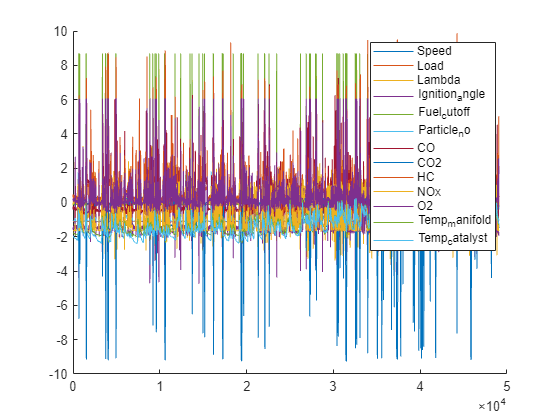

figure;
hold on;
for i = 1:length(datasets.Properties.VariableNames)
    plot(table2array(datasets(:, i)))
end
hold off;
legend(datasets.Properties.VariableNames)

### Fuel Cutoff Data Preprocessing

fc_index_0 = find(bosch_datasets.Fuel_cutoff < 0);
fc_index_1 = find(bosch_datasets.Fuel_cutoff > 0);
% fc_index_1 = find(bosch_datasets.Fuel_cutoff > 8);
datasets.Fuel_cutoff(fc_index_0) = 0;
datasets.Fuel_cutoff(fc_index_1) = 1;

% Exclude the Fuel Cutoff data along preprocessing
fuel_cutoff = datasets.Fuel_cutoff;
datasets = datasets(:, ~strcmp(datasets.Properties.VariableNames, 'Fuel_cutoff'));

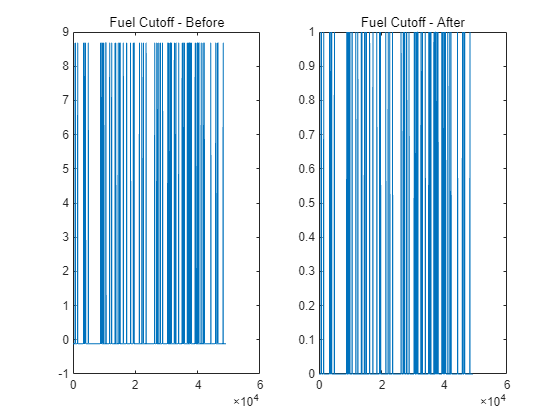

figure;
subplot(1,2,1);
plot(bosch_datasets.Fuel_cutoff)
title('Fuel Cutoff - Before')
subplot(1,2,2);
plot(fuel_cutoff)
title('Fuel Cutoff - After')

### 1.1. Correlation Check

To identify relationships between variables, a **Correlation Heatmap** was generated, and variables with correlations greater than **80%** were examined.

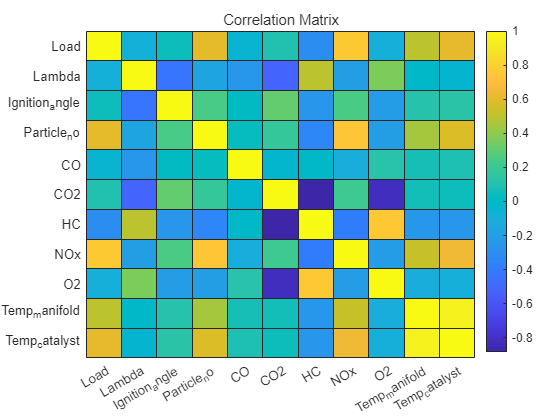

figure;
variable_names = datasets.Properties.VariableNames(2:end);
corr_matrix = corrcoef(table2array(datasets(:, 2:end)));
heatmap(corr_matrix, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Correlation Matrix', 'Colormap', parula);

disp(corr_matrix);

    1.0000   -0.0824    0.0473    0.6096   -0.0496    0.1017   -0.3072    0.7608   -0.0917    0.4973    0.6117
   -0.0824    1.0000   -0.4339   -0.1681   -0.2488   -0.5138    0.4989   -0.2045    0.3630   -0.0138   -0.0394
    0.0473   -0.4339    1.0000    0.2425    0.0173    0.3141   -0.2522    0.2550   -0.2196    0.1134    0.1312
    0.6096   -0.1681    0.2425    1.0000    0.0319    0.1774   -0.3397    0.7395   -0.1999    0.4472    0.5786
   -0.0496   -0.2488    0.0173    0.0319    1.0000   -0.0325   -0.0036   -0.1073    0.1216    0.0720    0.0850
    0.1017   -0.5138    0.3141    0.1774   -0.0325    1.0000   -0.8833    0.2130   -0.8245    0.0649    0.0484
   -0.3072    0.4989   -0.2522   -0.3397   -0.0036   -0.8833    1.0000   -0.3975    0.7505   -0.2462   -0.2563
    0.7608   -0.2045    0.2550    0.7395   -0.1073    0.2130   -0.3975    1.0000   -0.2142    0.5263    0.6398
   -0.0917    0.3630   -0.2196   -0.1999    0.1216   -0.8245    0.7505   -0.2142    1.0000   -0.1053   -0.0919
 

% Find Variables that Correlation is higher than threshold
corr_threshold = 0.8;
high_corr = abs(corr_matrix) > corr_threshold;
high_corr = high_corr - eye(size(high_corr));
[rows, cols] = find(high_corr);

cor_idx = unique(max(rows, cols));
variable_names = datasets.Properties.VariableNames(2:end);
cor_vars = variable_names(cor_idx);

disp(['Highly Correlated Variables: ', strjoin(cor_vars, ', ')]);

Highly Correlated Variables: HC, O2, Temp_catalyst


### 1.2. Box Plot

**Box plot** is a visual tool that displays the distribution of data, showing the **minimum, first quartile, median, third quartile, and maximum**, which helps visualize the spread and detect outliers in the dataset.

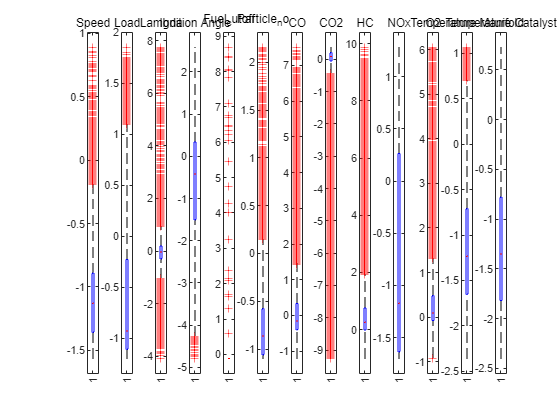

figure;
subplot(1,13,1);
boxplot(bosch_datasets.Speed)
title("Speed")
subplot(1,13,2);
boxplot(bosch_datasets.Load)
title("Load")
subplot(1,13,3);
boxplot(bosch_datasets.Lambda)
title("Lambda")
subplot(1,13,4);
boxplot(bosch_datasets.Ignition_angle)
title("Ignition Angle")
subplot(1,13,5);
boxplot(bosch_datasets.Fuel_cutoff)
title("Fuel_cutoff")
subplot(1,13,6);
boxplot(bosch_datasets.Particle_no)
title("Particle_no")
subplot(1,13,7);
boxplot(bosch_datasets.CO)
title("CO")
subplot(1,13,8);
boxplot(bosch_datasets.CO2)
title("CO2")
subplot(1,13,9);
boxplot(bosch_datasets.HC)
title("HC")
subplot(1,13,10);
boxplot(bosch_datasets.NOx)
title("NOx")
subplot(1,13,11);
boxplot(bosch_datasets.O2)
title("O2")
subplot(1,13,12);
boxplot(bosch_datasets.Temp_manifold)
title("Temperature Manifold")
subplot(1,13,13);
boxplot(bosch_datasets.Temp_catalyst)
title("Temperature Catalyst")

### 2.1. Outlier Check & Replacement

The data revealed a significant presence of outliers during the sensor data acquisition process. To replace these outliers, the **Linear Interpolation** method was used.

% Outlier Replacement - Linear interpolation
outlier_eli = [];
for i = 1:length(datasets.Properties.VariableNames)
    temp = filloutliers(table2array(datasets(:, i)), 'linear');
    outlier_eli = [outlier_eli, temp];
end
outlier_eli = array2table(outlier_eli);
outlier_eli.Properties.VariableNames = datasets.Properties.VariableNames;

% Update
datasets = outlier_eli;

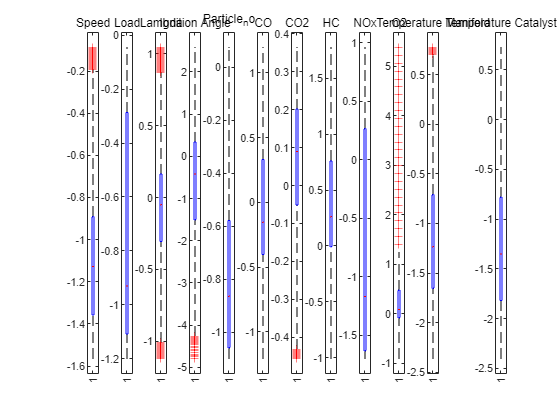

figure;
subplot(1,13,1);
boxplot(datasets.Speed)
title("Speed")
subplot(1,13,2);
boxplot(datasets.Load)
title("Load")
subplot(1,13,3);
boxplot(datasets.Lambda)
title("Lambda")
subplot(1,13,4);
boxplot(datasets.Ignition_angle)
title("Ignition Angle")
subplot(1,13,5);
boxplot(datasets.Particle_no)
title("Particle_no")
subplot(1,13,6);
boxplot(datasets.CO)
title("CO")
subplot(1,13,7);
boxplot(datasets.CO2)
title("CO2")
subplot(1,13,8);
boxplot(datasets.HC)
title("HC")
subplot(1,13,9);
boxplot(datasets.NOx)
title("NOx")
subplot(1,13,10);
boxplot(datasets.O2)
title("O2")
subplot(1,13,11);
boxplot(datasets.Temp_manifold)
title("Temperature Manifold")
subplot(1,13,13);
boxplot(datasets.Temp_catalyst)
title("Temperature Catalyst")

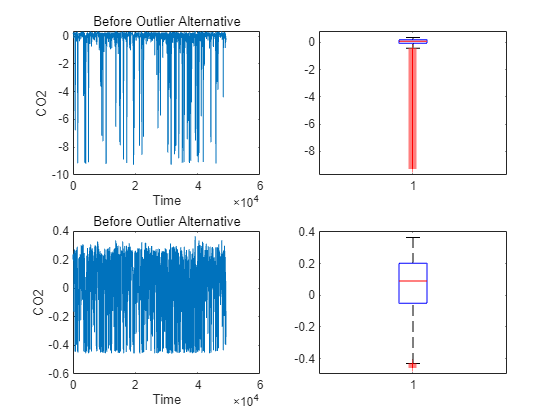

figure;
subplot(2,2,1);
plot(bosch_datasets.CO2)
xlabel("Time");
ylabel("CO2");
title("Before Outlier Alternative");
subplot(2,2,2);
boxplot(bosch_datasets.CO2)
subplot(2,2,3);
plot(datasets.CO2)
xlabel("Time");
ylabel("CO2");
title("Before Outlier Alternative");
subplot(2,2,4);
boxplot(datasets.CO2)

Compared to the previous plot, it is evident that the number of outliers has significantly decreased.

### 2.5. Noise Reduction - Low pass filter

In this dataset, the key focus is not on observing changes over time (as in typical time series data), but rather on analyzing the distribution of variables within each case. 

However, due to significant noise in the acquired data, the variables are distributed with a large standard deviation, making it difficult to train the model effectively.

To address this issue, a **Butterworth Lowpass Filter** was applied, which helps reduce the standard deviation of the data by smoothing out high-frequency noise. This filtering process allows the underlying distribution characteristics of the data to become clearer, enhancing the model's ability to learn from the data.

% Filter Structure
filtered_datasets = datasets;
variables = datasets.Properties.VariableNames;

d1 = designfilt("lowpassiir",FilterOrder=12, ...
    HalfPowerFrequency=0.05,DesignMethod="butter");

% Apply Butterworth Lowpass Filter

for i = 1:width(datasets)
    filtered_datasets.(variables{i}) = filtfilt(d1, datasets.(variables{i}));
end

%update
datasets = filtered_datasets;

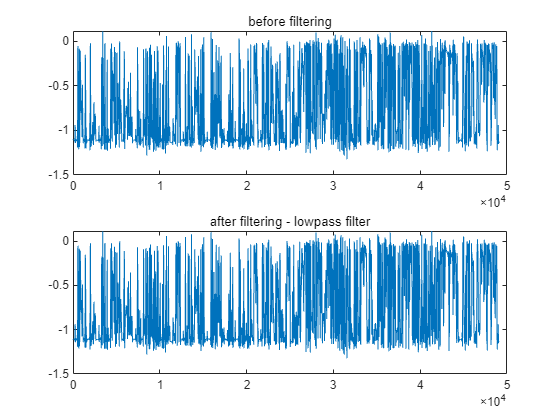

figure;

subplot(2,1,1);
plot(filtered_datasets.Load)
title('before filtering')

subplot(2,1,2);
plot(datasets.Load)
title('after filtering - lowpass filter')

Compared to the previous plot, after applying the **Butterworth Lowpass Filter**, the standard deviation of the data was significantly reduced, allowing the distribution characteristics of the data to be more clearly defined. This smoothing process helped eliminate high-frequency noise, making the patterns in the variables easier to interpret and thus improving the data's suitability for training.

### 2.3. Min-Max Scaling

As in the previous Baseline Journal, **Min-Max Scaling** was applied. This method normalizes the data by scaling the values of each variable to a range between 0 and 1, ensuring consistency across different units for better comparison and analysis during the modeling process.

% Min-Max Scaling
scaled_datasets = datasets;
for i = 1:width(datasets)
    scaled_datasets.(variables{i}) = normalize(datasets.(variables{i}), 'range');
end

%update
datasets = scaled_datasets;

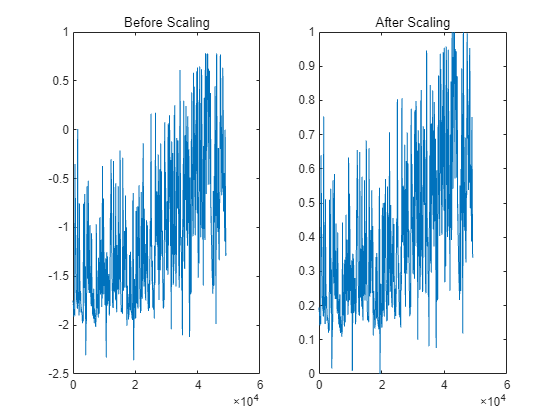

figure;

subplot(1,2,1);
plot(filtered_datasets.Temp_manifold);
title('Before Scaling')

subplot(1,2,2);
plot(datasets.Temp_manifold);
title('After Scaling')

% Add saved fuel cutoff data
datasets = datasets(:, ~strcmp(datasets.Properties.VariableNames, 'fuel_cutoff'));
added_datasets = [datasets, array2table(fuel_cutoff)];

%update
datasets = added_datasets;
clear added_datasets;

## 3. Classification

#### Train/Test Data Split

The **train** and **test datasets** were randomly split in an 80% : 20% ratio. This ensures that 80% of the data is used for model training and 20% is reserved for testing the model's performance on unseen data. 

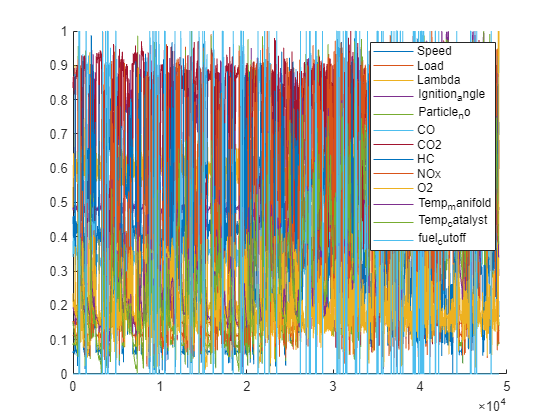

figure;
hold on;
for i = 1:length(datasets.Properties.VariableNames)
    plot(table2array(datasets(:, i)))
end
hold off;
legend(datasets.Properties.VariableNames)

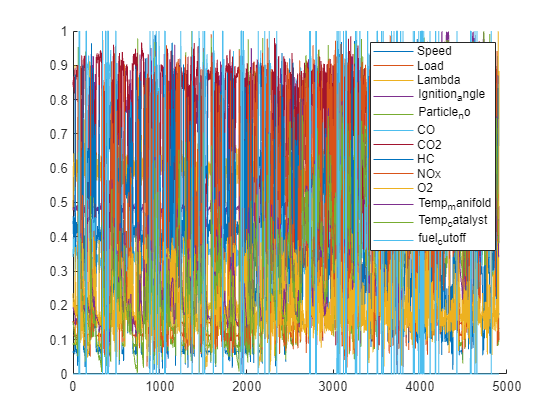

% downsized = cvpartition(height(datasets), 'HoldOut', 0.025);
% downsized_datasets = datasets(test(downsized), :)
% Down Sampling
t = 10;
downsampled_datasets = datasets(1:t:end, :);

figure;
hold on;
for i = 1:length(downsampled_datasets.Properties.VariableNames)
    plot(table2array(downsampled_datasets(:, i)))
end
hold off;
legend(downsampled_datasets.Properties.VariableNames)

%update
datasets = downsampled_datasets;

cv = cvpartition(height(datasets), 'HoldOut', 0.2);
Trainset = datasets(training(cv), :);
Testset = datasets(test(cv), :);

X_train = [Trainset.Speed, Trainset.Load, Trainset.Lambda, Trainset.Ignition_angle, Trainset.fuel_cutoff];
Y_train = [Trainset.Particle_no, Trainset.CO, Trainset.CO2, Trainset.HC, Trainset.NOx, Trainset.O2, Trainset.Temp_manifold, Trainset.Temp_catalyst];

X_test = [Testset.Speed, Testset.Load, Testset.Lambda, Testset.Ignition_angle, Testset.fuel_cutoff];
Y_test = [Testset.Particle_no, Testset.CO, Testset.CO2, Testset.HC, Testset.NOx, Testset.O2, Testset.Temp_manifold, Testset.Temp_catalyst];

writematrix(X_train, 'X_train.csv');
writematrix(Y_train, 'Y_train.csv');
writematrix(X_test, 'X_test.csv');
writematrix(Y_test, 'Y_test.csv');

### 3.2. MOGP

tic
% 5. MOGP 대신 각 출력 변수에 대해 가우시안 프로세스 회귀 모델 학습 (학습 데이터 사용)
gprMdl_CO = fitrgp(X_train,Y_train(:,1),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');  % CO 예측 모델
% gprMdl_CO = fitrgp(X_train,Y_train(:,1));
% gprMdl_HC = fitrgp(X_train, Y_train);  % HC 예측 모델
% gprMdl_CO2 = fitrgp(X_train, Y_train(:, 3));  % O2 예측 모델
% gprMdl_O2 = fitrgp(X_train, Y_train(:, 4));  % O2 예측 모델
% gprMdl_Lambda = fitrgp(X_train, Y_train(:, 5));  % O2 예측 모델
% gprMdl_AFR = fitrgp(X_train, Y_train(:, 6));  % Lambda 예측 모델
toc

경과 시간은 36.428024초입니다.


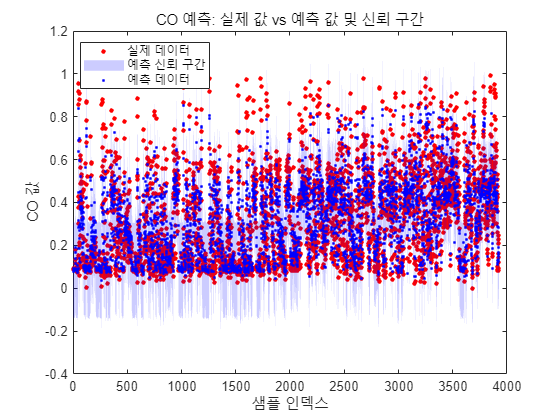

% GPR 모델 생성
% gprMdl_CO = fitrgp(X_train, Y_train(:,1), 'Basis', 'linear', ...
%       'FitMethod', 'exact', 'PredictMethod', 'exact');

% 학습 데이터에 대해 CO 예측 및 표준편차 계산
[ypred_CO_train, ystd_CO_train] = predict(gprMdl_CO, X_train);

% 실제 CO 값 (Y_train의 첫 번째 열)
actual_CO_train = Y_train(:, 1);

% 예측 신뢰 구간 설정 (예: 95% 신뢰 구간)
conf_interval = 1.96 * ystd_CO_train;  % 95% 신뢰 구간

% 예측된 값과 실제 값을 비교하는 그래프 생성
train_size = length(Y_train);
figure();
plot(1:train_size, actual_CO_train, 'r.', 'MarkerSize', 10);  % 실제 CO 값
hold on;

% 예측 값의 범위 (신뢰 구간) 추가
fill([1:train_size, fliplr(1:train_size)], ...
    [ypred_CO_train - conf_interval; flipud(ypred_CO_train + conf_interval)], ...
    'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');  % 신뢰 구간의 범위

% 예측 값 추가
plot(1:train_size, ypred_CO_train, 'b.', 'LineWidth', 1.5);  % 예측된 CO 값

xlabel('샘플 인덱스');
ylabel('CO 값');
legend({'실제 데이터', '예측 신뢰 구간', '예측 데이터'}, 'Location', 'Best');
title('CO 예측: 실제 값 vs 예측 값 및 신뢰 구간');
hold off;

rmse_CO_train = sqrt(mean((actual_CO_train - ypred_CO_train).^2))

rmse_CO_train = 0.1094


L = resubLoss(gprMdl_CO)

L = 0.0120

% 선형 회귀 모델 훈련
linearMdl_CO = fitlm(X_train, Y_train(:,1));

% 학습 데이터에 대해 CO 예측
ypred_CO_linear_train = predict(linearMdl_CO, X_train);

% 실제 CO 값 (Y_train의 첫 번째 열)
actual_CO_train = Y_train(:, 1);

% RMSE 계산
rmse_CO_linear_train = sqrt(mean((actual_CO_train - ypred_CO_linear_train).^2));

% 결과 출력
fprintf('CO 예측 (선형 회귀)의 RMSE: %.4f\n', rmse_CO_linear_train);

CO 예측 (선형 회귀)의 RMSE: 0.1385


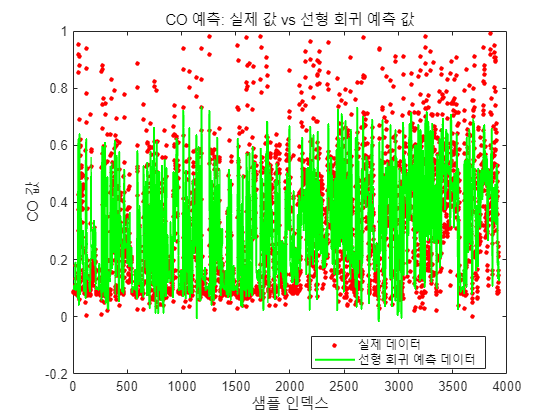


% 예측된 값과 실제 값을 비교하는 그래프 생성
train_size = length(Y_train);
figure();
plot(1:train_size, actual_CO_train, 'r.', 'MarkerSize', 10);  % 실제 CO 값
hold on;
plot(1:train_size, ypred_CO_linear_train, 'g', 'LineWidth', 1.5);  % 선형 회귀 예측 CO 값
xlabel('샘플 인덱스');
ylabel('CO 값');
legend({'실제 데이터', '선형 회귀 예측 데이터'}, 'Location', 'Best');
title('CO 예측: 실제 값 vs 선형 회귀 예측 값');
hold off;

% 학습할 출력 변수 수
num_outputs = size(Y_train, 2);

% GPR 모델을 출력 변수별로 저장할 셀 배열
gprModels = cell(1, num_outputs);

% 각 출력 변수에 대한 예측 결과 시각화
num_outputs = size(Y_train, 2);  % 출력 변수 수
train_size = length(Y_train);  % 학습 데이터의 크기

% 다중 출력 모델을 사용하여 예측 수행 (위의 코드 참고)
ypred_train = zeros(size(Y_train));
for i = 1:num_outputs
    ypred_train(:, i) = predict(gprModels{i}, X_train);
end

다음 사용 중 오류가 발생함: predict (86번 라인)
"predict" 명령에 대한 호출 구문이 유효하지 않습니다. 자세한 내용을 보려면 "help predict"을(를) 입력하십시오.


% 그래프 생성
figure;
for i = 1:num_outputs
    subplot(num_outputs, 1, i);  % 각 출력 변수에 대해 개별 그래프 생성
    plot(1:train_size, Y_train(:, i), 'r.', 'MarkerSize', 10);  % 실제 값
    hold on;
    plot(1:train_size, ypred_train(:, i), 'b-', 'LineWidth', 1.5);  % 예측 값
    xlabel('샘플 인덱스');
    ylabel(['출력 변수 ' num2str(i) ' 값']);
    legend({'실제 데이터', '예측 데이터'}, 'Location', 'Best');
    title(['출력 변수 ' num2str(i) '의 실제 값 vs 예측 값']);
    hold off;
end

% 전체 그래프에 대한 설명 추가
sgtitle('MOGP 예측 결과: 실제 값 vs 예측 값');
% 각 출력 변수에 대한 예측 결과 시각화
num_outputs = size(Y_train, 2);  % 출력 변수 수
train_size = length(Y_train);  % 학습 데이터의 크기

% 다중 출력 모델을 사용하여 예측 수행 (위의 코드 참고)
ypred_train = zeros(size(Y_train));
for i = 1:num_outputs
    ypred_train(:, i) = predict(gprModels{i}, X_train);
end

% 그래프 생성
figure;
for i = 1:num_outputs
    subplot(num_outputs, 1, i);  % 각 출력 변수에 대해 개별 그래프 생성
    plot(1:train_size, Y_train(:, i), 'r.', 'MarkerSize', 10);  % 실제 값
    hold on;
    plot(1:train_size, ypred_train(:, i), 'b-', 'LineWidth', 1.5);  % 예측 값
    xlabel('샘플 인덱스');
    ylabel(['출력 변수 ' num2str(i) ' 값']);
    legend({'실제 데이터', '예측 데이터'}, 'Location', 'Best');
    title(['출력 변수 ' num2str(i) '의 실제 값 vs 예측 값']);
    hold off;
end

% 전체 그래프에 대한 설명 추가
sgtitle('MOGP 예측 결과: 실제 값 vs 예측 값');



## 4. Result & Discussion

The comparison between the model performance before and after data preprocessing is as follows.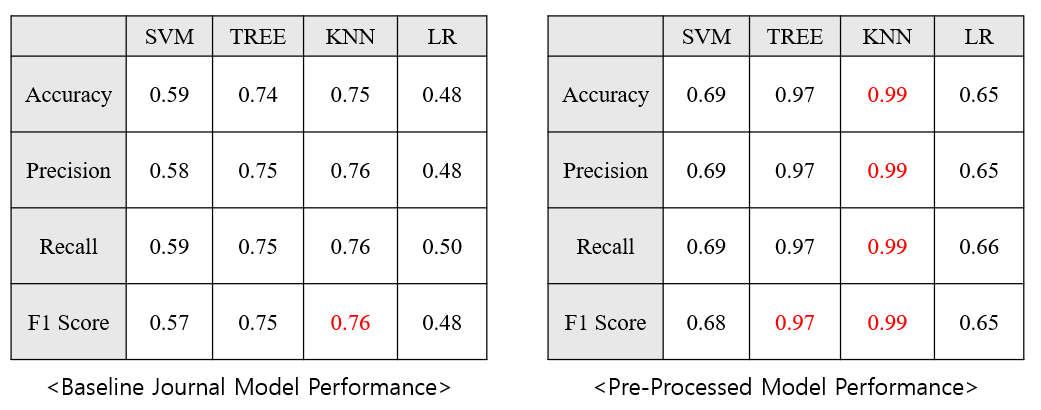

After applying **Data Preprocessing**, the model's performance, as measured by the F1 Score, improved from **76% to 99%**, increasing classification accuracy by 23%. 

While both **SVM** and **Logistic Regression** also showed performance improvements, the significant gains in **Decision Tree** and **KNN** can be attributed to the following reasons:

- The **KNN** model, being distance-based, benefited from having variables with similar patterns (e.g., **MAP, TPS, CO**), which allowed it to classify closely related data points more effectively.

- The **Decision Tree** model, with its clear classification rules, was well-suited to the **EngineFaultDB** dataset, which contains multiple input variables, making it an ideal model for this dataset.

- Although both **KNN** and **Decision Tree** are typically vulnerable to noise, the application of the **Butterworth Low-Pass filter** helped mitigate this issue, leading to the significant performance improvement observed.